Bewegungsgleichung:

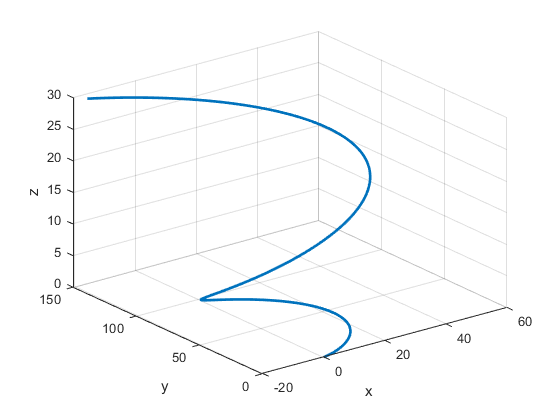

R_0 = [0; 0; 0];
V_0 = [0; 0; 0];
t = linspace(0, 20, 200);
A = [5 * cos(t/2); 5 * sin(t/2); 0.2 * ones(size(t/2))]; % Erhöhte Beschleunigung
V = cumtrapz(t/2, A, 2) + V_0;

R = R_0 + cumtrapz(t/2, V, 2) + 0.5 * cumtrapz(t/2, A, 2) .* t;

figure;
plot3(R(1,:), R(2,:), R(3,:), 'LineWidth', 2);
xlabel('x');
ylabel('y');
zlabel('z');
grid on;

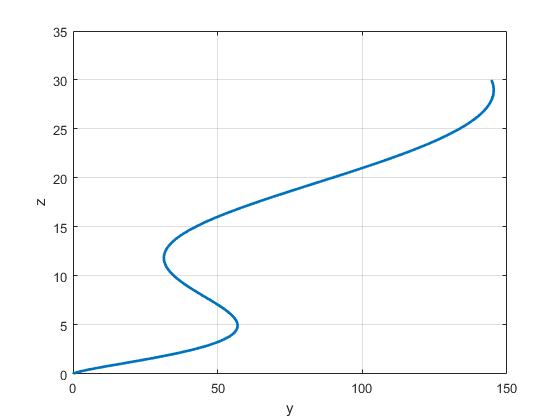

figure(1);
plot(R(2,:), R(3,:), 'LineWidth', 2);
ylabel('z');
xlabel('y');
grid on;

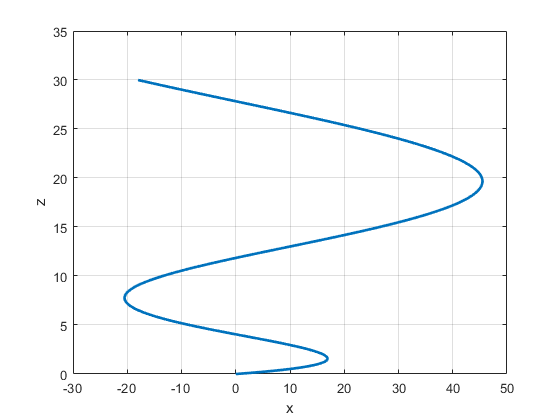


figure(2);
plot(R(1,:), R(3,:), 'LineWidth', 2);
ylabel('z');
xlabel('x');
grid on;

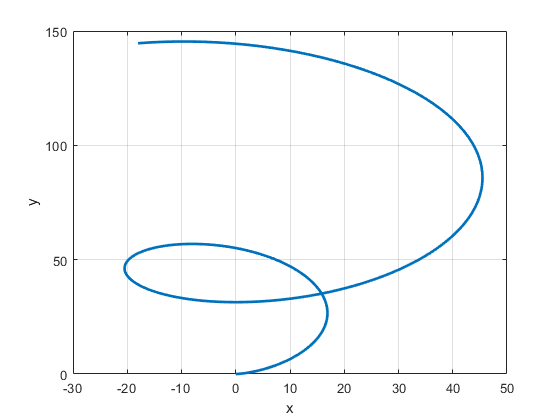


figure(3);
plot(R(1,:), R(2,:), 'LineWidth', 2);
ylabel('y');
xlabel('x');
grid on;

Gemessene Werte:

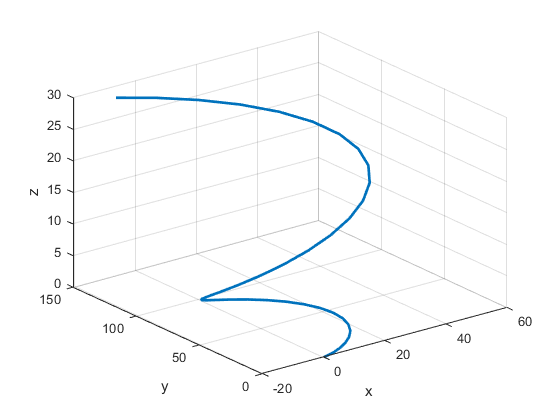

R_measured = extract_every_third_column(R);
figure;
plot3(R_measured(1,:), R_measured(2,:), R_measured(3,:), 'LineWidth', 2);
xlabel('x');
ylabel('y');
zlabel('z');
grid on;

% y = awgn(R_measured,5);
% 
% figure;
% plot3(y(1,:), y(2,:), y(3,:), 'LineWidth', 2);
% xlabel('x');
% ylabel('y');
% zlabel('z');
% grid on;


R_measured(3,:)

ans =          0    0.0189    0.0758    0.1705    0.3030    0.4735    0.6818    0.9280    1.2121    1.5341    1.8939    2.2916    2.7272    3.2007    3.7120    4.2613    4.8484    5.4733    6.1362    6.8369    7.5756    8.3521    9.1664   10.0187   10.9088   11.8368   12.8027   13.8065   14.8481   15.9276   17.0450   18.2003   19.3934   20.6245   21.8934   23.2002   24.5448   25.9274   27.3478   28.8061


for i=1:length(R_measured(3,:))
    % Zufällige Werte zwischen -2 und 2 generieren
    randomValues = 4 * rand(1, 1) - 2;
    R_measured(3,i) = R_measured(3,i) + randomValues;
end
R_measured(3,:)

ans =     0.8416   -0.7336   -0.7584    1.5719    1.9496    1.0306   -0.2967   -0.7173    2.5651    1.8729    3.6863    0.5357    3.0658    2.3411    5.0230    3.0252    4.6185    5.0470    7.4425    7.5444    6.4060    7.6245    7.7017   10.7045   11.1928   10.5159   11.3933   13.7108   16.4805   16.1363   15.1768   16.4157   20.6137   20.4300   21.4240   24.3587   24.0020   26.0568   28.1944   30.2920


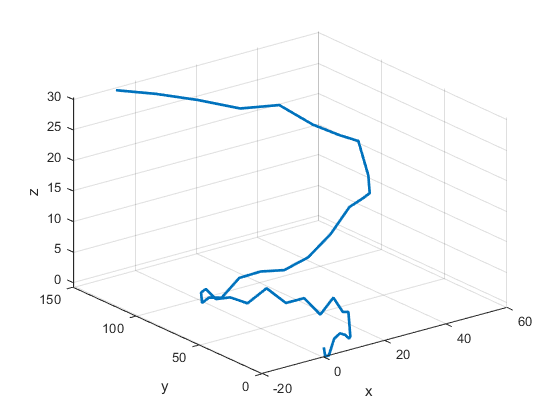

figure;
plot3(R_measured(1,:), R_measured(2,:), R_measured(3,:), 'LineWidth', 2);
xlabel('x');
ylabel('y');
zlabel('z');
grid on;

% Gegebene 3D-Punkte (X, Y, Z)
% R_measured = 3x20
points = transpose(R_measured)

points =          0         0    0.8416
    0.4692    0.0529   -0.7336
    1.8277    0.4155   -0.7584
    3.9327    1.3682    1.5719
    6.5599    3.1358    1.9496
    9.4238    5.8647    1.0306
   12.2030    9.6079   -0.2967
   14.5692   14.3176   -0.7173
   16.2176   19.8459    2.5651
   16.8958   25.9553    1.8729



% Zeitpunkte für die Punkte (optional)
% t = 1x200
t_measured = extract_every_third_column(t)

t_measured =          0    0.5025    1.0050    1.5075    2.0101    2.5126    3.0151    3.5176    4.0201    4.5226    5.0251    5.5276    6.0302    6.5327    7.0352    7.5377    8.0402    8.5427    9.0452    9.5477   10.0503   10.5528   11.0553   11.5578   12.0603   12.5628   13.0653   13.5678   14.0704   14.5729   15.0754   15.5779   16.0804   16.5829   17.0854   17.5879   18.0905   18.5930   19.0955   19.5980


% time = 20x1
time = transpose(t_measured)

time =          0
    0.5025
    1.0050
    1.5075
    2.0101
    2.5126
    3.0151
    3.5176
    4.0201
    4.5226




% Berechnung der Geschwindigkeit
velocityX = diff(points(:, 1)) ./ diff(time);
velocityY = diff(points(:, 2)) ./ diff(time);
velocityZ = diff(points(:, 3)) ./ diff(time);

% Geschwindigkeitsvektor erstellen
% velocityVector = [VX1, VY1, VZ1;
%                   VX2, VY2, VZ2;
%                   VX3, VY3, VZ3;
%                   ...];
velocityVector = [velocityX, velocityY, velocityZ];

% Berechnung der Beschleunigung
accelerationX = diff(velocityVector(:, 1)) ./ diff(time(1:end-1));
accelerationY = diff(velocityVector(:, 2)) ./ diff(time(1:end-1));
accelerationZ = diff(velocityVector(:, 3)) ./ diff(time(1:end-1));

% Beschleunigungsvektor erstellen
accelerationVector = [accelerationX, accelerationY, accelerationZ];


% Ergebnis ausgeben
disp(velocityVector);

    0.9337    0.1052   -3.1348
    2.7035    0.7215   -0.0493
    4.1888    1.8961    4.6373
    5.2281    3.5174    0.7517
    5.6992    5.4304   -1.8289
    5.5306    7.4490   -2.6413
    4.7087    9.3723   -0.8370
    3.2803   11.0014    6.5321
    1.3497   12.1576   -1.3775
   -0.9288   12.6975    3.6087
   -3.3623   12.5270   -6.2697
   -5.7349   11.6109    5.0348
   -7.8250    9.9781   -1.4421
   -9.4241    7.7211    5.3369
  -10.3542    4.9914   -3.9755
  -10.4842    1.9891    3.1706
   -9.7430   -1.0515    0.8527
   -8.1271   -3.8792    4.7671
   -5.7047   -6.2461    0.2028
   -2.6133   -7.9268   -2.2655
    0.9482   -8.7378    2.4248
    4.7322   -8.5539    0.1536
    8.4593   -7.3209    5.9757
   11.8386   -5.0624    0.9716
   14.5896   -1.8828   -1.3470
   16.4640    2.0380    1.7461
   17.2660    6.4537    4.6117
   16.8697   11.0679    5.5118
   15.2313   15.5533   -0.6849
   12.3969   19.5749   -1.9095
    8.5025   22.8144    2.4655
    3.7683   24.9941    8.3539
   -1.51

% Ergebnis ausgeben
disp(accelerationVector);

    3.5218    1.2265    6.1400
    2.9559    2.3373    9.3264
    2.0682    3.2265   -7.7323
    0.9374    3.8069   -5.1353
   -0.3356    4.0170   -1.6168
   -1.6355    3.8272    3.5906
   -2.8425    3.2421   14.6645
   -3.8420    2.3007  -15.7399
   -4.5342    1.0743    9.9224
   -4.8427   -0.3393  -19.6579
   -4.7215   -1.8229   22.4959
   -4.1594   -3.2494  -12.8890
   -3.1821   -4.4914   13.4901
   -1.8508   -5.4321  -18.5317
   -0.2588   -5.9746   14.2209
    1.4751   -6.0507   -4.6126
    3.2156   -5.6273    7.7895
    4.8204   -4.7101   -9.0828
    6.1519   -3.3445   -4.9120
    7.0874   -1.6139    9.3338
    7.5301    0.3658   -4.5197
    7.4169    2.4538   11.5859
    6.7249    4.4943   -9.9581
    5.4745    6.3275   -4.6140
    3.7301    7.8023    6.1553
    1.5960    8.7873    5.7026
   -0.7888    9.1822    1.7910
   -3.2603    8.9259  -12.3314
   -5.6405    8.0030   -2.4369
   -7.7499    6.4465    8.7063
   -9.4210    4.3376   11.7179
  -10.5106    1.8013  -17.3519
  -10.91

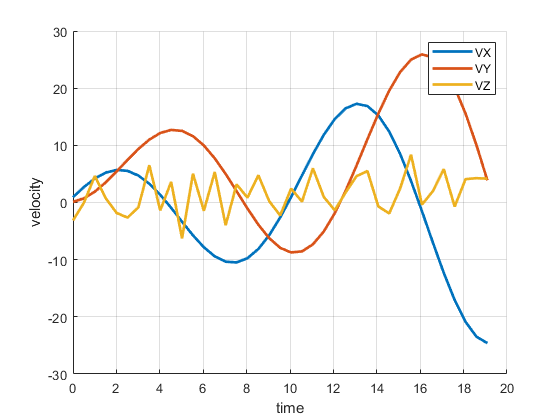

velocityVector = transpose(velocityVector);
time = transpose(time(1:end-1));

figure;
hold on;

plot(time, velocityVector(1,:), 'LineWidth', 2);
plot(time, velocityVector(2,:), 'LineWidth', 2);
plot(time, velocityVector(3,:), 'LineWidth', 2);

xlabel('time');
ylabel('velocity');
grid on;

legend('VX', 'VY', 'VZ');

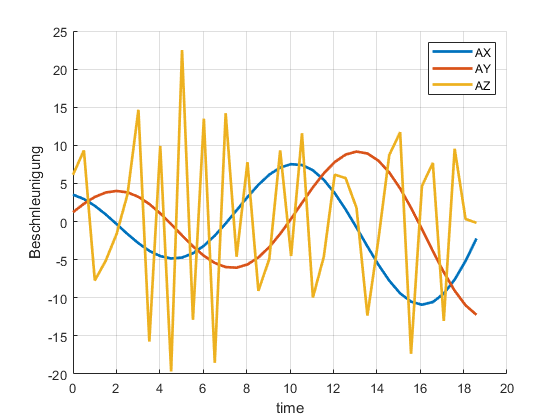

accelerationVector = transpose(accelerationVector);
time = transpose(time(1:end-1));

figure;
hold on;

plot(time, accelerationVector(1,:), 'LineWidth', 2);
plot(time, accelerationVector(2,:), 'LineWidth', 2);
plot(time, accelerationVector(3,:), 'LineWidth', 2);

xlabel('time');
ylabel('Beschnleunigung');
grid on;

legend('AX', 'AY', 'AZ');

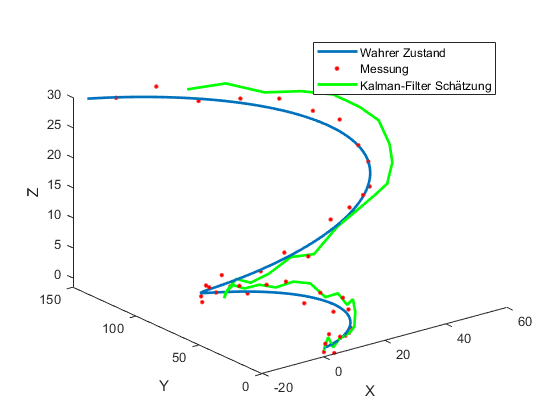

% Gegebenes Beispiel
R_0 = [0; 0; 0];
V_0 = [0; 0; 0];
t = linspace(0, 20, 200);
A = [5 * cos(t/2); 5 * sin(t/2); 0.2 * ones(size(t/2))]; % Erhöhte Beschleunigung
V = cumtrapz(t/2, A, 2) + V_0;

R = R_0 + cumtrapz(t/2, V, 2) + 0.5 * cumtrapz(t/2, A, 2) .* t;

R_measured = extract_every_third_column(R);
for i=1:length(R_measured(3,:))
    % Zufällige Werte zwischen -2 und 2 generieren
    randomValues = 4 * rand(1, 1) - 2;
    R_measured(3,i) = R_measured(3,i) + randomValues;
end

% Kalman-Filter Parameter
dt = 0.5;                % Abtastzeit
A_kalman = [1 dt dt^2/2; 0 1 dt; 0 0 1];       % Zustandsübergangsmatrix
B_kalman = [dt^3/6; dt^2/2; dt];               % Steuerungsmatrix (Beschleunigung)
C_kalman = eye(3);                             % Messmatrix (direkte Messung von X, Y, Z)
Q_kalman = diag([0.8, 0.8, 0.8]);              % Prozessrauschkovarianz
R_kalman = diag([0.3, 0.5, 0.5]);              % Messrauschkovarianz

% Initialisierung
x_kalman = zeros(3, length(R_measured));
P_kalman = zeros(3, 3, length(R_measured));

% Schätzung mit Kalman-Filter
for i = 1:length(R_measured)
    % Vorhersage
    if i == 1
        x_pred = [0; 0; 0];
        P_pred = eye(3);
    else
        x_pred = A_kalman * x_kalman(:, i-1) + B_kalman .* A(:, i-1);
        P_pred = A_kalman * P_kalman(:, :, i-1) * A_kalman' + Q_kalman;
    end
    
    % Korrektur
    K = P_pred * C_kalman' / (C_kalman * P_pred * C_kalman' + R_kalman);
    x_kalman(:, i) = x_pred + K * (R_measured(:, i) - C_kalman * x_pred);
    P_kalman(:, :, i) = (eye(3) - K * C_kalman) * P_pred;
end

% Ergebnisse anzeigen
figure;
hold on;
plot3(R(1,:), R(2,:), R(3,:), 'LineWidth', 2);
plot3(R_measured(1,:), R_measured(2,:), R_measured(3,:), 'r.', 'MarkerSize', 10);
plot3(x_kalman(1,:), x_kalman(2,:), x_kalman(3,:), 'g-', 'LineWidth', 2);
legend('Wahrer Zustand', 'Messung', 'Kalman-Filter Schätzung');
xlabel('X');
ylabel('Y');
zlabel('Z');
view(3);

function new_array = extract_every_third_column(R)
    new_array = R(:, 1:5:end);
end